clc;clear all


`INITIAL CONDITIONS`


X(1) = 0; 
T(1) = 714; %K

YNH3 = 0.0148056;
YN2 = 0.253713;
YH2 = 0.722858;
YAr = 0.00319126;
YO2 = 0.00543192;

Y = YNH3 + YN2 + YH2 + YAr+YO2;

F0TOTAL = 414;%kmol/hr
F0N2 = (F0TOTAL*YN2);%kmol/hr
F0H2 = (F0TOTAL*YH2);
F0NH3 = (F0TOTAL*YNH3);
F0Ar = (F0TOTAL*YAr);
F0O2 = (F0TOTAL*YO2);

mdot = 919.93;%kg/hr
void = 0.46;

D = 0.45;
A = (pi*D^2)/4;
MAXvol = 0.11;
MAXvol2 = 0.08;
MAXvol3 = 0.17;

`LITERATURE CONSTANTS`

RATE OF REACTION

k0 = 8.85E14; %kJ/kmol
E2 = 1.7056E5; % kJ/kmol
R = 8.314; % kJ/kmol K
alpha = 0.5;

`INCREMENTATION `

dV = 0.00005; %steps in length'
i = 2:MAXvol3/dV;
P = zeros(length(i));
P(:) = 150; %atm


`EFFECTIVENESS FACTOR`

if (P(1) >= 188.5) && (P(1) <= 250) 
    b0 = -8.2125534;
    b1 = 0.03774149;
    b2 = 6.190112;
    b3 = -5.354571E-5;
    b4 = -20.86963;
    b5 = 2.379142E-8;
    b6 = 27.88403;
elseif (P(1) >= 111.5) && (P(1) < 188.5) 
    b0 = -17.539096;
    b1 = 0.07697849;
    b2 = 6.900548;
    b3 = -1.082790E-4;
    b4 = -26.42469;
    b5 = 4.927648E-8;
    b6 = 38.93727;
end


`FIRST REACTOR`

for i = 2:MAXvol/dV

    V(i) = (i-1)*dV;
    eta(i-1) = b0+b1*T(i-1)+b2*X(i-1)+b3*(T(i-1)^2)+b4*(X(i-1)^2)+b5*(T(i-1)^3)+b6*(X(i-1)^3);
    fugnh3(i-1) = 0.1438996 +((0.2028538E-2)*T(i-1))-((0.448762E-3)*P(i-1))-((0.1142945E-5)*T(i-1)^2)+((0.2761216E-6)*P(i-1));
    fugn2(i-1) =  0.93431737 + ((0.3101804E-3)*T(i-1)) + ((0.295896E-3)*P(i-1)) - ((0.2707279E-6)*(T(i-1))^2) + (0.477507E-6*(P(i-1))^2);
    fugh2(i-1) = exp( exp(-3.8402*T(i-1)^0.125+0.541)*P(i-1) - exp(-0.1263*T(i-1)^0.5-15.98)*P(i-1)^2 + 300*exp(-0.011901*T(i-1)-5.941)*exp(P(i-1)/300));
    ynh3(i-1) = (YNH3 + 2*X(i-1)*YN2)/(1-2*X(i-1)*YN2);
    yn2(i-1) = (YN2*(1-X(i-1)))/(1-2*X(i-1)*YN2);
    yh2(i-1) = (YH2 - 3*X(i-1)*YN2)/(1-2*X(i-1)*YN2);
    yar(i-1) = YAr/(1-2*X(i-1)*YN2);
    yo2(i-1) = YO2/(1-2*X(i-1)*YN2);
    anh3(i-1) = ynh3(i-1)*fugnh3(i-1)*P(i-1);
    an2(i-1) = yn2(i-1)*fugn2(i-1)*P(i-1);
    ah2(i-1) = yh2(i-1)*fugh2(i-1)*P(i-1);
    K(i-1) = 10^(-2.691122*log10(T(i-1))-(5.519265*10^(-5))*T(i-1)+(1.848863*10^(-7))*T(i-1)^2+(2001.6/T(i-1))+2.6899);
    Kequil(i-1) = sqrt((anh3(i-1)^2)/(an2(i-1)*ah2(i-1)^3));
    Xequil(i-1) = Kequil(i-1)/(1+Kequil(i-1));
    k2(i-1) = k0*exp(-E2/(R*T(i-1)));
    Rnh3(i-1) = 2*k2(i-1)*(K(i-1)^2*an2(i-1)*((ah2(i-1)^3)/(anh3(i-1)^2))^alpha-((anh3(i-1)^2)/(ah2(i-1)^3))^(1-alpha)); %kmol/m3.hr
    dHr(i-1) = 4.184*(-(P(i-1))*(0.54526+(840.609)/(T(i-1))+(459.734E6)/(T(i-1)^3))-5.34685*T(i-1)-(0.2525E-3)*T(i-1)^2+(1.69167E-6)*T(i-1)^3-9157.09); %kJ/kmol
    CpH2(i-1) = 4.184*(6.952+((-0.04567E-2)*(T(i-1)))+((0.09563E-5)*(T(i-1))^2)+((-0.2079E-9)*(T(i-1))^3));
    CpN2(i-1) = 4.184*(6.903+((-0.03753E-2)*(T(i-1)))+((0.193E-5)*(T(i-1))^2)+((-0.6861E-9)*(T(i-1))^3));
    CpAr(i-1) = 4.184*(4.75);
    CpNH3(i-1) = 4.184*(6.5846 - T(i-1)*(0.61251E-2) + (T(i-1)^2)*(0.23663E-5)-(T(i-1)^3)*(1.5981E-9)+96.1678-0.067571*P(i-1)+T(i-1)*(-0.2225+(1.6847E-4)*(P(i-1)))+(T(i-1)^2)*((1.289E-4)-(1.0095E-7)*P(i-1)));
    Cpmix(i-1) = yh2(i-1)*CpH2(i-1) + ynh3(i-1)*CpNH3(i-1) + yn2(i-1)*CpN2(i-1) + CpAr(i-1)*yar(i-1);
    
    dG(i-1) = -dHr(i-1)*Rnh3(i-1)*V(i);
    dR(i-1) = (F0N2*CpN2(i-1) + F0NH3*CpNH3(i-1) + F0H2*CpH2(i-1) + F0Ar*CpAr(i-1))*(T(i-1)-T(1));

    dXdV = (eta(i-1) * Rnh3(i-1) )/(2*F0N2);
    dTdV = (-(dHr(i-1))*eta(i-1)*Rnh3(i-1))/(F0TOTAL*Cpmix(i-1));
    %dPdL = (mu*u*150*(1-void)^2)/((void^3)*(dp^2)) - (1.75*rho*(u^2)*(1-void))/((void^3)*(dp))
    X(i) = X(i-1) + dXdV*dV;
    T(i) = T(i-1) + dTdV*dV;
    %P(i) = P(i-1) + dPdL*dL
end



SECOND REACTOR

T2(1) = 755;
X2(1) = X(1,end);

F1N2 = F0N2 - F0N2*X(1,end);
F1H2 = F0H2 - F0N2*X(1,end)*3;
F1NH3 = F0NH3 + X2(1,end)*2*F0H2;
F1Ar = F0Ar;
F1O2 = F0O2;

F1TOTAL = F1Ar + F1H2 + F1NH3 + F1N2 + F1O2;

YNH3_2 = F1NH3/F1TOTAL;
YH2_2 = F1H2/F1TOTAL;
YN2_2 = F1N2/F1TOTAL;
YO2_2 = F1O2/F1TOTAL;
YAr_2 = F1Ar/F1TOTAL;



for  j = 2 : MAXvol2/dV

    V2(j) = (j-1)*dV+ MAXvol;
    eta2(j-1) = b0+b1*T2(j-1)+b2*X2(j-1)+b3*(T2(j-1)^2)+b4*(X2(j-1)^2)+b5*(T2(j-1)^3)+b6*(X2(j-1)^3);
    fugnh3(j-1) = 0.1438996 +((0.2028538E-2)*T2(j-1))-((0.448762E-3)*P(j-1))-((0.1142945E-5)*T2(j-1)^2)+((0.2761216E-6)*P(j-1));
    fugn2(j-1) =  0.93431737 + ((0.3101804E-3)*T2(j-1)) + ((0.295896E-3)*P(j-1)) - ((0.2707279E-6)*(T2(j-1))^2) + (0.477507E-6*(P(j-1))^2);
    fugh2(j-1) = exp( exp(-3.8402*T2(j-1)^0.125+0.541)*P(j-1) - exp(-0.1263*T2(j-1)^0.5-15.98)*P(j-1)^2 + 300*exp(-0.011901*T2(j-1)-5.941)*exp(P(j-1)/300));
    ynh3_2(j-1) = (YNH3 + 2*X2(j-1)*YN2)/(1-2*X2(j-1)*YN2);
    yn2_2(j-1) = (YN2*(1-X2(j-1)))/(1-2*X2(j-1)*YN2);
    yh2_2(j-1) = (YH2 - 3*X2(j-1)*YN2)/(1-2*X2(j-1)*YN2);
    yar_2(j-1) = YAr/(1-2*X2(j-1)*YN2);
    yo2_2(j-1) = YO2/(1-2*X2(j-1)*YN2);
    anh3(j-1) = ynh3_2(j-1)*fugnh3(j-1)*P(j-1);
    an2(j-1) = yn2_2(j-1)*fugn2(j-1)*P(j-1);
    ah2(j-1) = yh2_2(j-1)*fugh2(j-1)*P(j-1);
    K2(j-1) = 10^(-2.691122*log10(T2(j-1))-(5.519265*10^(-5))*T2(j-1)+(1.848863*10^(-7))*T2(j-1)^2+(2001.6/T2(j-1))+2.6899);
    Kequil(j-1) = sqrt((anh3(j-1)^2)/(an2(j-1)*ah2(j-1)^3));
    Xequil(j-1) = Kequil(j-1)/(1+Kequil(j-1));
    k2(j-1) = k0*exp(-E2/(R*T2(j-1)));
    Rnh3_2(j-1) = 2*k2(j-1)*(K2(j-1)^2*an2(j-1)*((ah2(j-1)^3)/(anh3(j-1)^2))^alpha-((anh3(j-1)^2)/(ah2(j-1)^3))^(1-alpha)); %kmol/m3.hr
    dHr(j-1) = 4.184*(-(P(j-1))*(0.54526+(840.609)/(T2(j-1))+(459.734E6)/(T2(j-1)^3))-5.34685*T2(j-1)-(0.2525E-3)*T2(j-1)^2+(1.69167E-6)*T2(j-1)^3-9157.09); %kJ/kmol
    CpH2(j-1) = 4.184*(6.952+((-0.04567E-2)*(T2(j-1)))+((0.09563E-5)*(T2(j-1))^2)+((-0.2079E-9)*(T2(j-1))^3));
    CpN2(j-1) = 4.184*(6.903+((-0.03753E-2)*(T2(j-1)))+((0.193E-5)*(T2(j-1))^2)+((-0.6861E-9)*(T2(j-1))^3));
    CpAr(j-1) = 4.184*(4.75);
    CpNH3(j-1) = 4.184*(6.5846 - T2(j-1)*(0.61251E-2) + (T2(j-1)^2)*(0.23663E-5)-(T2(j-1)^3)*(1.5981E-9)+96.1678-0.067571*P(j-1)+T2(j-1)*(-0.2225+(1.6847E-4)*(P(j-1)))+(T2(j-1)^2)*((1.289E-4)-(1.0095E-7)*P(j-1)));
    Cpmix(j-1) = yh2_2(j-1)*CpH2(j-1) + ynh3_2(j-1)*CpNH3(j-1) + yn2_2(j-1)*CpN2(j-1) + yar_2(j-1)*CpAr(j-1);

    dXdV = (eta2(j-1) * Rnh3_2(j-1) )/(2*F1N2);
    dTdV = (-(dHr(j-1))*eta2(j-1)*Rnh3_2(j-1))/(F1TOTAL*Cpmix(j-1));
    %dPdL = (mu*u*150*(1-void)^2)/((void^3)*(dp^2)) - (1.75*rho*(u^2)*(1-void))/((void^3)*(dp))
    X2(j) = X2(j-1) + dXdV*dV;
    T2(j) = T2(j-1) + dTdV*dV;
    %P(i) = P(i-1) + dPdL*dL
end


THIRD REACTOR

T3(1) = 701;
X3(1) = X2(1,j);

F2N2 = F0N2 - F0N2*X3(1);
F2H2 = F0H2 - F0N2*X3(1)*3;
F2NH3 = F0NH3 + X3(1)*2;
F2Ar = F0Ar;
F2O2 = F0O2;

F2TOTAL = F2Ar + F2H2 + F2NH3 + F2N2 + F2O2;

YNH3_3 = F2NH3/F2TOTAL;
YH2_3 = F2H2/F2TOTAL;
YN2_3 = F2N2/F2TOTAL;
YO2_3 = F2O2/F2TOTAL;
YAr_3 = F2Ar/F2TOTAL;

for  k = 2 : MAXvol3/dV

    V3(k) = (k-1)*dV + MAXvol + MAXvol2;
    eta3(k-1) = b0+b1*T3(k-1)+b2*X3(k-1)+b3*(T3(k-1)^2)+b4*(X3(k-1)^2)+b5*(T3(k-1)^3)+b6*(X3(k-1)^3);
    fugnh3(k-1) = 0.1438996 +((0.2028538E-2)*T3(k-1))-((0.448762E-3)*P(k-1))-((0.1142945E-5)*T3(k-1)^2)+((0.2761216E-6)*P(k-1));
    fugn2(k-1) =  0.93431737 + ((0.3101804E-3)*T3(k-1)) + ((0.295896E-3)*P(k-1)) - ((0.2707279E-6)*(T3(k-1))^2) + (0.477507E-6*(P(k-1))^2);
    fugh2(k-1) = exp( exp(-3.8402*T3(k-1)^0.125+0.541)*P(k-1) - exp(-0.1263*T3(k-1)^0.5-15.98)*P(k-1)^2 + 300*exp(-0.011901*T3(k-1)-5.941)*exp(P(k-1)/300));
    ynh3_3(k-1) = (YNH3 + 2*X3(k-1)*YN2)/(1-2*X3(k-1)*YN2);
    yn2_3(k-1) = (YN2*(1-X3(k-1)))/(1-2*X3(k-1)*YN2);
    yh2_3(k-1) = (YH2 - 3*X3(k-1)*YN2)/(1-2*X3(k-1)*YN2);
    yar_3(k-1) = YAr/(1-2*X3(k-1)*YN2);
    anh3(k-1) = ynh3_3(k-1)*fugnh3(k-1)*P(k-1);
    an2(k-1) = yn2_3(k-1)*fugn2(k-1)*P(k-1);
    ah2(k-1) = yh2_3(k-1)*fugh2(k-1)*P(k-1);
    K3(k-1) = 10^(-2.691122*log10(T3(k-1))-(5.519265*10^(-5))*T3(k-1)+(1.848863*10^(-7))*T3(k-1)^2+(2001.6/T3(k-1))+2.6899);
    Kequil(k-1) = sqrt((anh3(k-1)^2)/(an2(k-1)*ah2(k-1)^3));
    Xequil(k-1) = Kequil(k-1)/(1+Kequil(k-1));
    k2(k-1) = k0*exp(-E2/(R*T3(k-1)));
    Rnh3_3(k-1) = 2*k2(k-1)*(K3(k-1)^2*an2(k-1)*((ah2(k-1)^3)/(anh3(k-1)^2))^alpha-((anh3(k-1)^2)/(ah2(k-1)^3))^(1-alpha)); %kmol/m3.hr
    dHr(k-1) = 4.184*(-(P(k-1))*(0.54526+(840.609)/(T3(k-1))+(459.734E6)/(T3(k-1)^3))-5.34685*T3(k-1)-(0.2525E-3)*T3(k-1)^2+(1.69167E-6)*T3(k-1)^3-9157.09); %kJ/kmol
    CpH2(k-1) = 4.184*(6.952+((-0.04567E-2)*(T3(k-1)))+((0.09563E-5)*(T3(k-1))^2)+((-0.2079E-9)*(T3(k-1))^3));
    CpN2(k-1) = 4.184*(6.903+((-0.03753E-2)*(T3(k-1)))+((0.193E-5)*(T3(k-1))^2)+((-0.6861E-9)*(T3(k-1))^3));
    CpAr(k-1) = 4.184*(4.75);
    CpNH3(k-1) = 4.184*(6.5846 - T3(k-1)*(0.61251E-2) + (T3(k-1)^2)*(0.23663E-5)-(T3(k-1)^3)*(1.5981E-9)+96.1678-0.067571*P(k-1)+T3(k-1)*(-0.2225+(1.6847E-4)*(P(k-1)))+(T3(k-1)^2)*((1.289E-4)-(1.0095E-7)*P(k-1)));
    Cpmix(k-1) = yh2_3(k-1)*CpH2(k-1) + ynh3_3(k-1)*CpNH3(k-1) + yn2_3(k-1)*CpN2(k-1) + CpAr(k-1)*yar_3(k-1);
    Cpmix2(k-1) = 35.31 + 0.02*T3(k-1) + 0.00000694*T3(k-1)^2-0.0056*(P(k-1)*101.325)+0.000014*(P(k-1)*101.325)*T3(k-1); %kJ/kmol
    dXdV = (eta3(k-1) * Rnh3_3(k-1) )/(2*F2N2);
    dTdV = (-(dHr(k-1))*eta3(k-1)*Rnh3_3(k-1))/(F2TOTAL*Cpmix(k-1));
    %dPdL = (mu*u*150*(1-void)^2)/((void^3)*(dp^2)) - (1.75*rho*(u^2)*(1-void))/((void^3)*(dp))
    X3(k) = X3(k-1) + dXdV*dV;
    T3(k) = T3(k-1) + dTdV*dV;
    %P(i) = P(i-1) + dPdL*dL
end

PLOTTING

Xeq = [0.245,0.109]

Xeq =     0.2450    0.1090


Teq = [759,853]

Teq =    759   853



Tcorrection = T(:,1:length(T)-1);
Vcorrection = V(:,1:length(V)-1);
Xcorrection = X(:,1:length(X)-1);

Max= V(i);
Total = (MAXvol + MAXvol2)-dV;
L2 = 1,MAXvol:(dV):Total;

L2 = 1

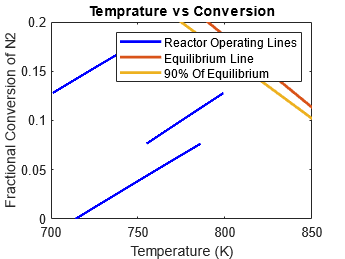


V2correction = V2(:,2:length(V2));

V3correction = V3(:,2:length(V3));
T3correction = T3(:,2:length(T3));


plot(T,X,"blue",'LineWidth',2)
hold on
plot(Teq,Xeq,'LineWidth',2)
plot(Teq,0.9*Xeq,'LineWidth',2)
plot(T2,X2,"blue",'LineWidth',2)
plot(T3,X3,"blue",'LineWidth',2)
ylim([0,0.2])
xlim([700,850])
% text(780,X(1,end)/2,"RE-601")
% text(780,X2(1,end)/2+X(1,end)/2,"RE-602")
% text(780,X3(1,end)/2+X2(1,end)/2,"RE-603")
title("Temprature vs Conversion")
xlabel("Temperature (K)")
ylabel("Fractional Conversion of N2")
legend("Reactor Operating Lines","Equilibrium Line","90% Of Equilibrium")
hold off

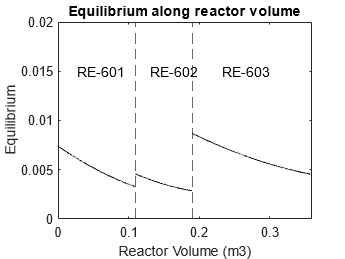



plot(Vcorrection,K,"black")
hold on
plot(V2correction,K2,"black")
plot(V3correction,K3,"black")
xline(MAXvol,'--')
xline(MAXvol+MAXvol2,'--')
ylim([0;0.02])
xlim([0,MAXvol2+MAXvol+MAXvol3])
text(0.25*MAXvol,0.015,"RE-601")
text((0.25*MAXvol2+MAXvol),0.015,"RE-602")
text((0.25*MAXvol3+MAXvol2+MAXvol),0.015,"RE-603")
title("Equilibrium along reactor volume")
ylabel("Equilibrium")
xlabel("Reactor Volume (m3)")
hold off

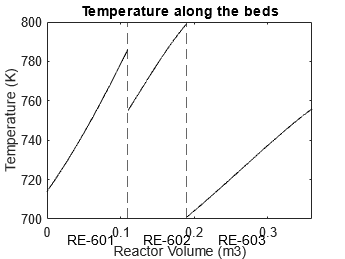



plot(V,T,"black")
hold on
plot(V2(1,2:end),T2(1,2:end),"black")
title("Temperature along the beds")
plot(V3(1,2:end),T3(1,2:end),"black")
xline(MAXvol,'--')
xline(MAXvol+MAXvol2,'--')
xlim([0,MAXvol2+MAXvol+MAXvol3])
text(0.25*MAXvol,690,"RE-601")
text((0.25*MAXvol2+MAXvol),690,"RE-602")
text((0.25*MAXvol3+MAXvol2+MAXvol),690,"RE-603")
ylabel("Temperature (K)")
xlabel("Reactor Volume (m3)")
hold off

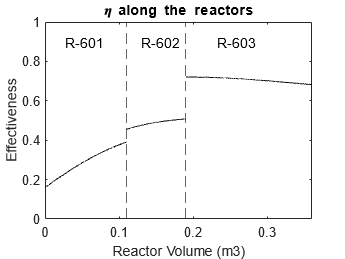



plot(Vcorrection,eta,"black")
hold on
plot(V2correction,eta2,"black")
plot(V3correction,eta3,"black")
xline(MAXvol,'--')
xline(MAXvol+MAXvol2,'--')
ylim([0;1])
xlim([0,MAXvol2+MAXvol+MAXvol3])
text(0.25*MAXvol,0.90,"R-601")
text((0.25*MAXvol2+MAXvol),0.90,"R-602")
text((0.25*MAXvol3+MAXvol2+MAXvol),0.90,"R-603")
title("\eta along the reactors")
ylabel("Effectiveness")
xlabel("Reactor Volume (m3)")
hold off

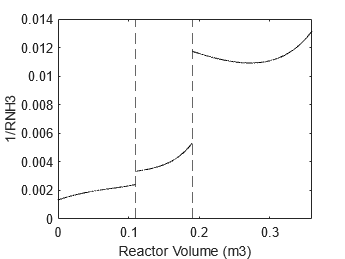




plot(Vcorrection,1./Rnh3,"black")
hold on
plot(V2correction,1./Rnh3_2,"black")
plot(V3correction,1./Rnh3_3,"black")
xline(MAXvol,'--')
xline(MAXvol+MAXvol2,'--')
xlim([0,MAXvol2+MAXvol+MAXvol3])
text(0.25*MAXvol,0.025,"RE-601")
text((0.25*MAXvol2+MAXvol),0.025,"RE-602")
text((0.25*MAXvol3+MAXvol2+MAXvol),0.025,"RE-603")
ylabel("1/RNH3")
xlabel("Reactor Volume (m3)")
hold off

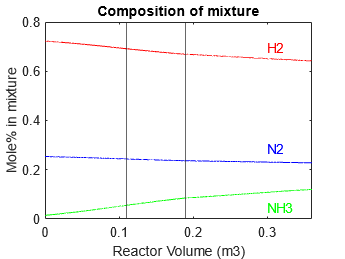



plot(Vcorrection,ynh3,"green")
hold on
plot(Vcorrection,yn2,"blue")
plot(Vcorrection,yh2,"red")
plot(V2correction,ynh3_2,"green")
plot(V2correction,yn2_2,"blue")
plot(V2correction,yh2_2,"red")
plot(V3correction,ynh3_3,"green")
plot(V3correction,yn2_3,"blue")
plot(V3correction,yh2_3,"red")
xline(MAXvol)
xline(MAXvol+MAXvol2)
xlim([0,MAXvol2+MAXvol+MAXvol3])
text(0.3,0.05,"NH3","Color","green")
text(0.3,0.29,"N2","Color","blue")
text(0.3,0.7,"H2","Color","red")
title("Composition of mixture")
ylabel("Mole% in mixture")
xlabel("Reactor Volume (m3)")
hold off

FINAL VALUES

X3(1) = X2(1,j);

F2N2 = F0N2 - F0N2*X3(1);
F2H2 = F0H2 - F0N2*X3(1)*3;
F2NH3 = F0NH3 + X3(1)*2;
F2Ar = F0Ar;
F2O2 = F0O2;

F2TOTAL = F2Ar + F2H2 + F2NH3 + F2N2 + F2O2;

YNH3_3 = F2NH3/F2TOTAL;
YH2_3 = F2H2/F2TOTAL;
YN2_3 = F2N2/F2TOTAL;
YO2_3 = F2O2/F2TOTAL;
YAr_3 = F2Ar/F2TOTAL;